## ECEN 142L Communications and Networking Lab 

## Lab 1: MATLAB Review

Over the next 10 weeks, we will be interacting with MATLAB quite a bit. Not only is it a powerful language, but it also provides many vital tools that make it critical to the workflow of a communications engineer. 

Today’s Objective: Flex our MATLAB muscles, and get comfortable doing the standard operations that we will be seeing frequently this quarter. If you are unfamiliar with any of the MATLAB commands we are using today or in the future, your first step should be to look up information on the MATLAB documentation site - these articles will likely answer any questions you may have. 

Part 1 - MATLAB Basics Open MATLAB, and create a new .m file by clicking the plus button in the top right corner. Save the file as Lab1.m in a location you will remember in the future. 

    Step 1: Enter the following lines into your new file: 

        x1 = [1,2,3,4]; 

        x2 = [3,4,5,6] %no semicolon 

To run the code, click run section at the top of the editor. Notice how the workspace (bottom left) now contains these variables. Comment on what the semicolon did to x1.

x1 = [1,2,3,4];
x2 = [3,4,5,6] %no semicolon

x2 =      3     4     5     6


**When running this code, we can see that x2 was printed out, but x1 wasn't. This is because there's no semicolon on the end of the x2 vector.**

We can concatenate arrays very easily with the bracket operators []. 

Run these two commands: 

        x3 = [x1 x2]; 

        x4 = [x1; x2]; 

Inspect the contents of x3 and x4 by double clicking on them in the workspace. Comment on what each command did.

x3 = [x1 x2];
x4 = [x1; x2];

**Because x3 didn't have semicolons to splice up the individual vectors, it made one large 1x8 vector with contents of x1 and x2 appended, whereas x4 made a 2x4 vector where x1 was row 1 and x2 was row 2.**

Many times, we may want to use the dimensions of these vectors/matrices in our program. Run the following two lines and comment on their output:             

        length(x3)

        size(x4)

We can also operate on every element in a matrix individually with the .* operator. Make a new variable x5 that is 5 times the elements of x4.

length(x3)

ans = 8

size(x4)

ans =      2     4


x5 = 5 .* x4;

**Length tells the column amount, size gives full dimensions.**

Start a new section of the code by typing %%. Next, run the commands: 

        clear; 

        clc; 

These two commands clear the workspace and command window respectively. Run the following commands in the newly cleared code section: 

        f = 5; 

        t = 1:0.01:2; 

        x = 3*cos(2*pi*f*t); 

        plot(t, x); 

        xlabel('Time'); 

        ylabel('Amplitude'); 

Inspect the resulting figure. Did it match what you expected?

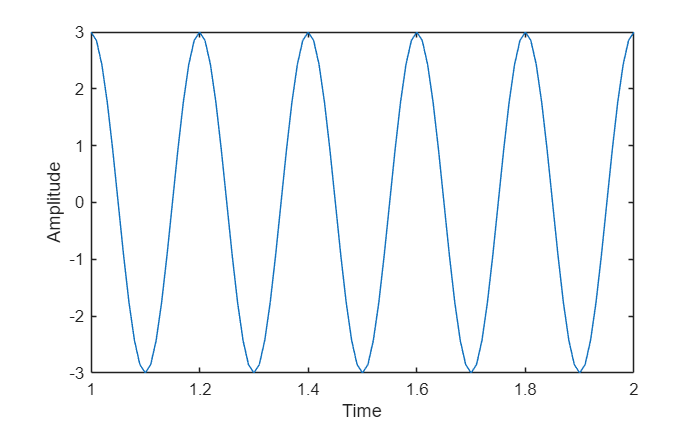

%% 
clear;
clc;

f = 5;
t = 1:0.01:2;
x = 3*cos(2*pi*f*t);

plot(t, x);
xlabel('Time');
ylabel('Amplitude');

**Yes the graph shows what I expect. Amplitudes of -3 and 3, a period of .2s (f=5), and a time span of 1 to 2 seconds.**

Next, create a new signal, y, that is a 4 Hz sine with amplitude 2, and plot it on the same plot with x. 

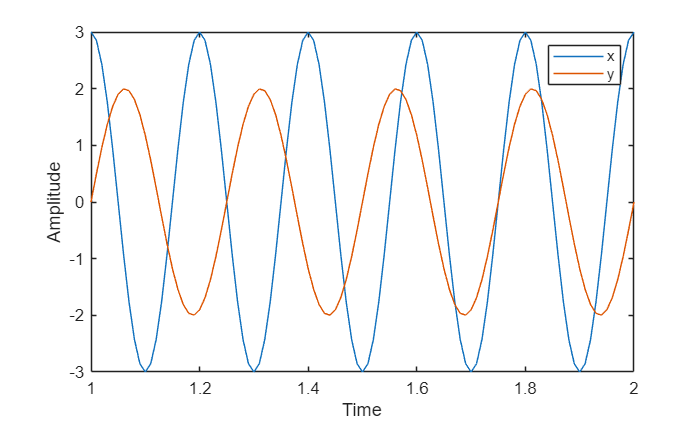

clear;
clc;

f = 5;
t = 1:0.01:2;
x = 3*cos(2*pi*f*t);
y = 2*sin(2*pi*4*t);

figure;
plot(t, x, t, y);
xlabel('Time');
ylabel('Amplitude');
legend('x', 'y')

Read the following page for guidance on step 3. https://www.mathworks.com/help/matlab/ref/subplot.html 

You will see the function sinc used often in communications. Run the following code to create 2 sincs: 

        clear; 

        clc; 

        x = -10:0.01:10;

        y1 = sinc(x); 

        y2 = sinc(x-2); 

To finish step 3, you will need to plot y1 and y2, as well as their sum and difference on one plot. Show your results from Part 1 to the TA.

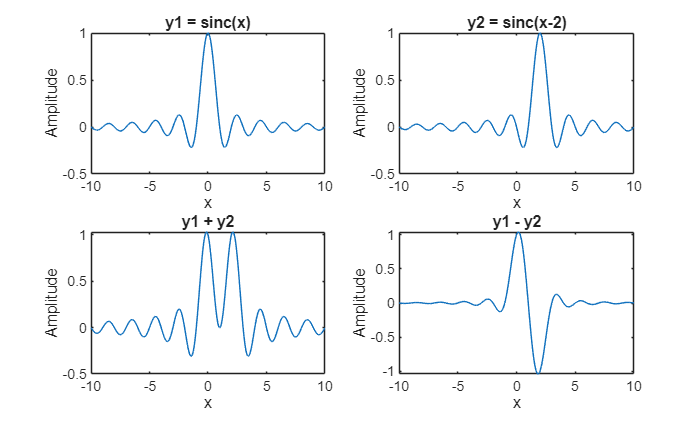

clear;
clc;

x = -10:0.01:10;
y1 = sinc(x);
y2 = sinc(x-2);

figure;
subplot(2,2,1);
plot(x, y1);
title('y1 = sinc(x)');
xlabel('x');
ylabel('Amplitude');

subplot(2,2,2);
plot(x, y2);
title('y2 = sinc(x-2)');
xlabel('x');
ylabel('Amplitude');

subplot(2,2,3);
plot(x, y1 + y2);
title('y1 + y2');
xlabel('x');
ylabel('Amplitude');

subplot(2,2,4);
plot(x, y1 - y2);
title('y1 - y2');
xlabel('x');
ylabel('Amplitude');

Part 2: MATLAB Programming constructs 

Step 1: Consult the following for some guidance with part 2: https://www.mathworks.com/help/matlab/ref/for.html 

Using what you have learned so far, write a for loop to sum all of the numbers from 1 to 100. At the end of the loop, use the disp() function to display the result, like so: 

        disp(sum);

clear;
clc;
sum = 0;
for (i = 1:100)
    sum = sum + i;
end
disp(sum);

        5050



Step 2: Use these links to help with step 2: https://www.mathworks.com/help/matlab/ref/if.html https://www.mathworks.com/help/matlab/ref/double.mod.html 

Write a program that prints the numbers from 1 to 100. But for multiples of three print “Fizz” instead of the number and for the multiples of five print “Buzz”. For numbers which are multiples of both three and five print “FizzBuzz”

clear;
clc;

for i = 1:100
    if (mod(i,3) == 0 && mod(i,5) == 0) disp('FizzBuzz');
    elseif (mod(i,3) == 0) disp('Fizz');
    elseif (mod(i,5) == 0) disp('Buzz');
    else disp(i);
    end
end

     1

     2



Fizz


     4



Buzz


Fizz


     7

     8



Fizz


Buzz


    11



Fizz


    13

    14



FizzBuzz


    16

    17



Fizz


    19



Buzz


Fizz


    22

    23



Fizz


Buzz


    26



Fizz


    28

    29



FizzBuzz


    31

    32



Fizz


    34



Buzz


Fizz


    37

    38



Fizz


Buzz


    41



Fizz


    43

    44



FizzBuzz


    46

    47



Fizz


    49



Buzz


Fizz


    52

    53



Fizz


Buzz


    56



Fizz


    58

    59



FizzBuzz


    61

    62



Fizz


    64



Buzz


Fizz


    67

    68



Fizz


Buzz


    71



Fizz


    73

    74



FizzBuzz


    76

    77



Fizz


    79



Buzz


Fizz


    82

    83



Fizz


Buzz


    86



Fizz


    88

    89



FizzBuzz


    91

    92



Fizz


    94



Buzz


Fizz


    97

    98



Fizz


Buzz


Step 3: Use this link to help with step 3: https://www.mathworks.com/help/matlab/ref/function.html 

Create a function called lab1_even_odd(x). This function should take 1 argument x, which is a list of numbers. The function should return two arrays, the first containing all of the even numbers in x, and the other containing all of the odd numbers. Call your function on an array of the numbers 1 to 100 to test it. Check the results to make sure they are what you expect. Show your results from Part 2 to the TA.

clear;
clc;

function [evens, odds] = lab1_even_odd(x)
    evens = x(mod(x,2) == 0);
    odds = x(mod(x,2) ~= 0);
end

x = 1:100;
[evens, odds] = lab1_even_odd(x);

disp(evens);

     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100



disp(odds);

     1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51    53    55    57    59    61    63    65    67    69    71    73    75    77    79    81    83    85    87    89    91    93    95    97    99



Part 3 - FFT demo 

For the final part of the lab, we will be doing a FFT in matlab. The FFT is an extremely important tool in all aspects of engineering analysis, but it is an especially important tool in communications. If you are unfamiliar with the FFT, the idea is this - by running the FFT on a signal, we can see what frequencies the signal is made up of, and how strong those frequencies are. Copy and run the code below: 

        clear; clc; 

        Fs = 1000; 

        ts = 1/Fs; 

        t = 0:ts:10; 

        x1 = cos(2*pi*100*t); 

        x2 = cos(2*pi*200*t); 

        x = x1+x2; 

        X = fft(x); 

        shift = fftshift(X); 

        freqaxis = Fs*(linspace(-0.5,0.5,length(x))); 

        plot(freqaxis, abs(shift)); 

        xlabel('Frequency'); 

        ylabel('Amplitude'); 

This is a pretty basic recipe for computing the FFT on a signal that you can reuse. Observe the plot - where are the peaks located?

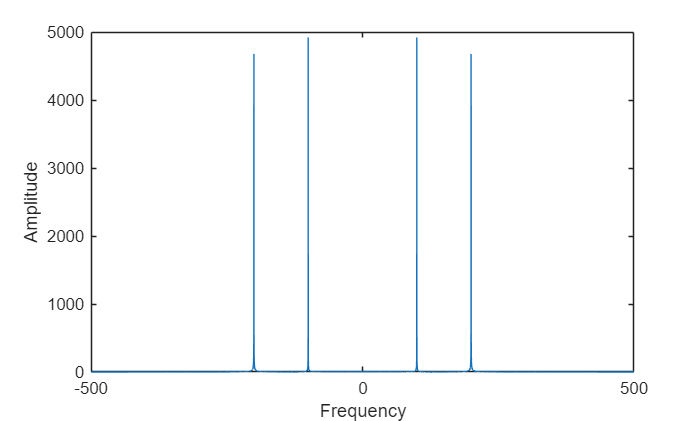

clear; clc;
Fs = 1000;
ts = 1/Fs;
t = 0:ts:10;
x1 = cos(2*pi*100*t);
x2 = cos(2*pi*200*t);
x = x1+x2;
X = fft(x);
shift = fftshift(X);
freqaxis = Fs*(linspace(-0.5,0.5,length(x)));

figure;
plot(freqaxis, abs(shift));
xlabel('Frequency');
ylabel('Amplitude');

**The peaks are located at -200, -100, 100, and 200 Hz.**

Finally, find the goat.wav file that came with this lab, and make sure it is in the same directory as your lab1.m file. To read it, use 

        [y, Fs] = audioread('goat.wav'); 

        sound(y,Fs); % listen to the audio 

Run the audio file through the FFT code instead of x as above. What does the plot look like this time? Show your results from Part 3 to the TA.

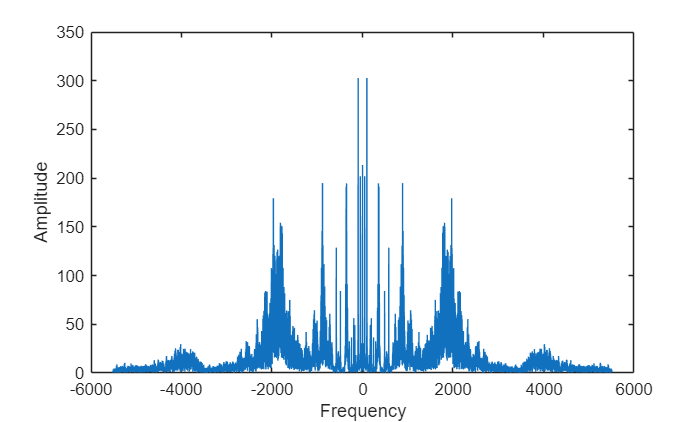

clear;
clc;
[y, Fs] = audioread('goat.wav');
sound(y, Fs);
Y = fft(y);
shift = fftshift(Y);
freqaxis = Fs*linspace(-0.5,0.5,length(y));

figure;
plot(freqaxis, abs(shift));
xlabel('Frequency');
ylabel('Amplitude');

**It's not nearly as clean and we see there's a lot more frequency components interspersed throughout the goat audio file. The most prominent frequencies are at (+ or -) 96Hz, 352Hz, 362Hz, 884Hz, and 1970 Hz.**